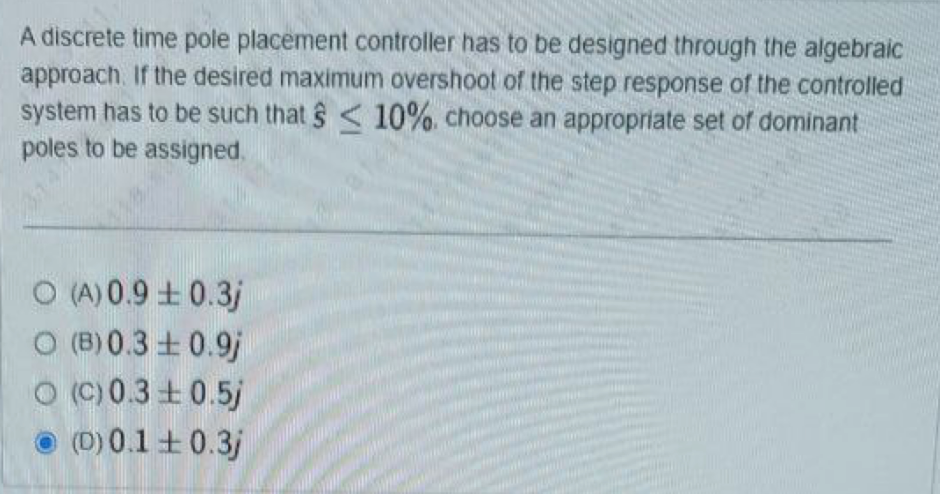

s_hat = 0.1;
zeta = abs(log(s_hat))/(sqrt(pi^2+log(s_hat)^2));

poles = [0.9+0.3j 0.3+0.9j 0.3+0.5j 0.1+0.3j];
% 
% plot(poles, 'bo')
% hold on
% zgrid(zeta, 100);

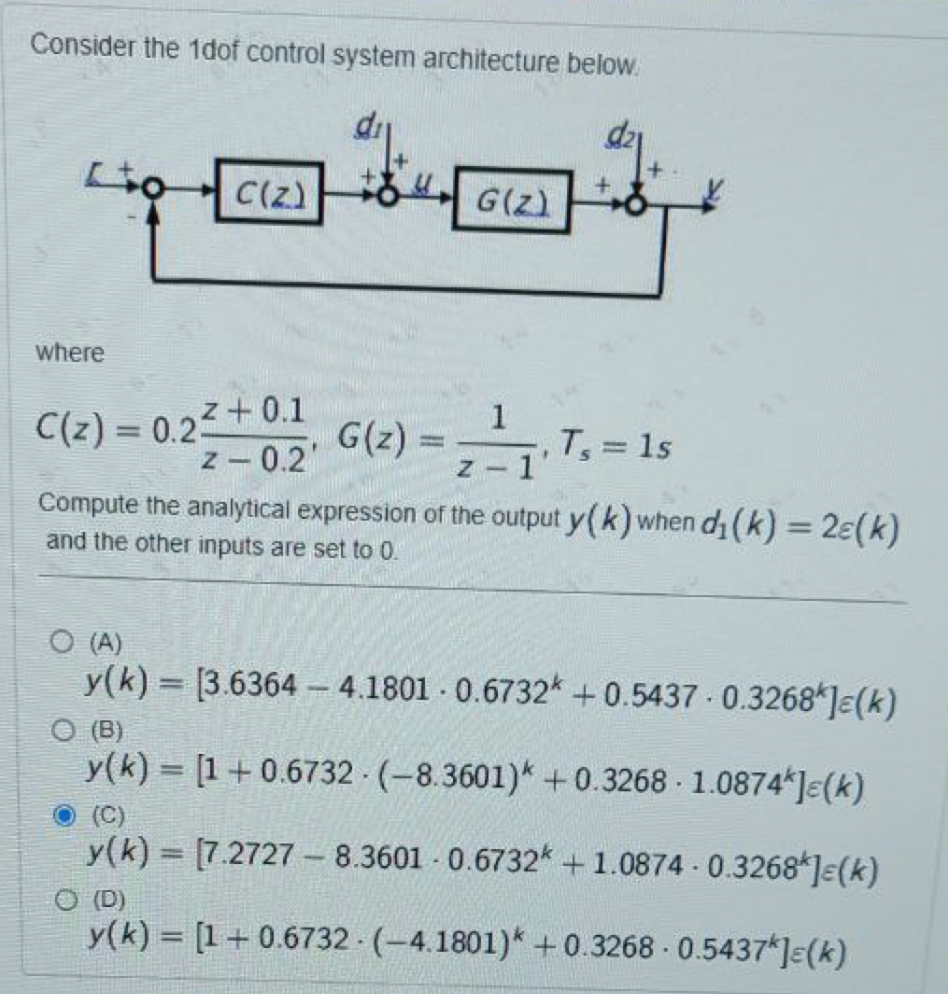

clear
% notes: don't forget zpk(minreal(...)
Ts = 1;
z = tf('z', Ts);
C = 0.2*(z+0.1)/(z-0.2);
G = 1/(z-1);
L = C*G;

W1 = zpk(minreal(G/(1+L), 1e-2)); 
D1 = 2*z/(z-1);

Y_D1 = zpk(minreal(W1*D1, 1e-2));

[ny, dy] = tfdata(Y_D1, 'v');
[r, p, k] = residuez(ny, dy)

r =     7.2727
   -8.3601
    1.0874


p =     1.0000
    0.6732
    0.3268


k = 0

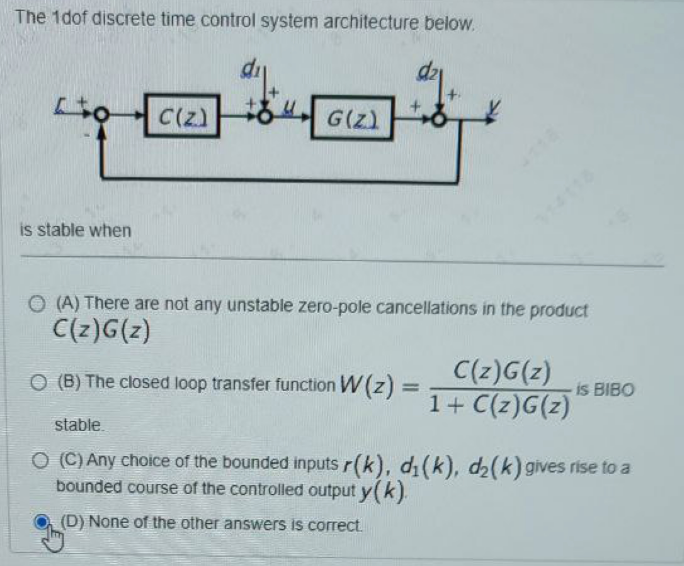

- is "right", but not correct. It could be that unstable poles are present.

- again is "right" but not correct. It could be that unstable z-p cancellations are present.

- is equal to bibo stability

- **correct**

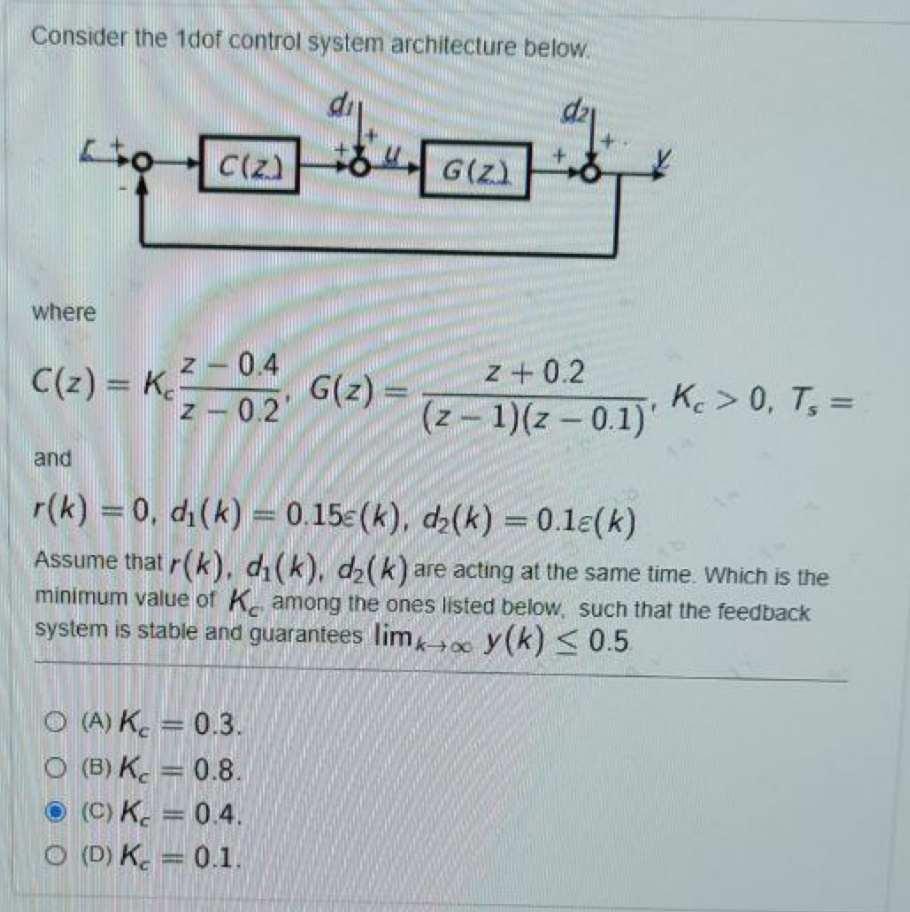

Y is given by the superposition of 3 effects, but we can see that r is zero. From steady state analysis we know that:

l1 = 1;

l2 = 0;

y_d2 depends on l = l1 + l2 -> since d_2 is a step => y_d2 = 0;

We just have to compute K wrt y_d1

From the formulary we get that K_l = Kc since G has poles in 1

clear
delta_1 = 0.15;
y_inf = 0.5; % y_delta1_inf = y_inf
Kc = delta_1/y_inf

Kc = 0.3000


% note: answer is 0.3, not 0.4

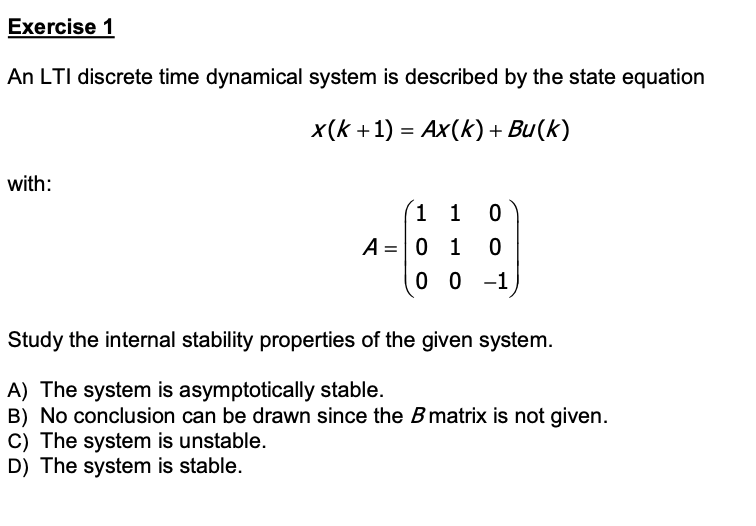

clear
A = [1 1 0; 0 1 0; 0 0 -1]

A =      1     1     0
     0     1     0
     0     0    -1


eig(A)

ans =      1
     1
    -1


% we have 2 eigs in 1 -> we must study the min poly multiplicity

% 2 methods
% 1:
roots(minpoly(A)) % e si vola

ans =    -1.0000
    1.0000
    1.0000


% 2: 
z = tf('z',1);
inv(z*eye(size(A,1))-A)


ans =
 
  From input 1 to output...
         1
   1:  -----
       z - 1
 
   2:  0
 
   3:  0
 
  From input 2 to output...
             1
   1:  -------------
       z^2 - 2 z + 1
 
         1
   2:  -----
       z - 1
 
   3:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
         1
   3:  -----
       z + 1
 
Sample time: 1 seconds
Discrete-time transfer function.


We have 2 poles in 1 in min polynomial => unstable

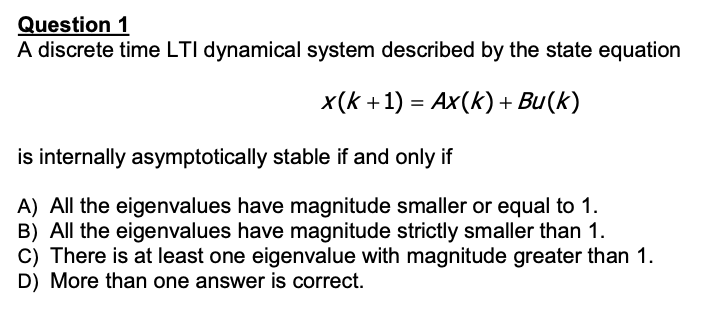

clearly C 1!1!1!

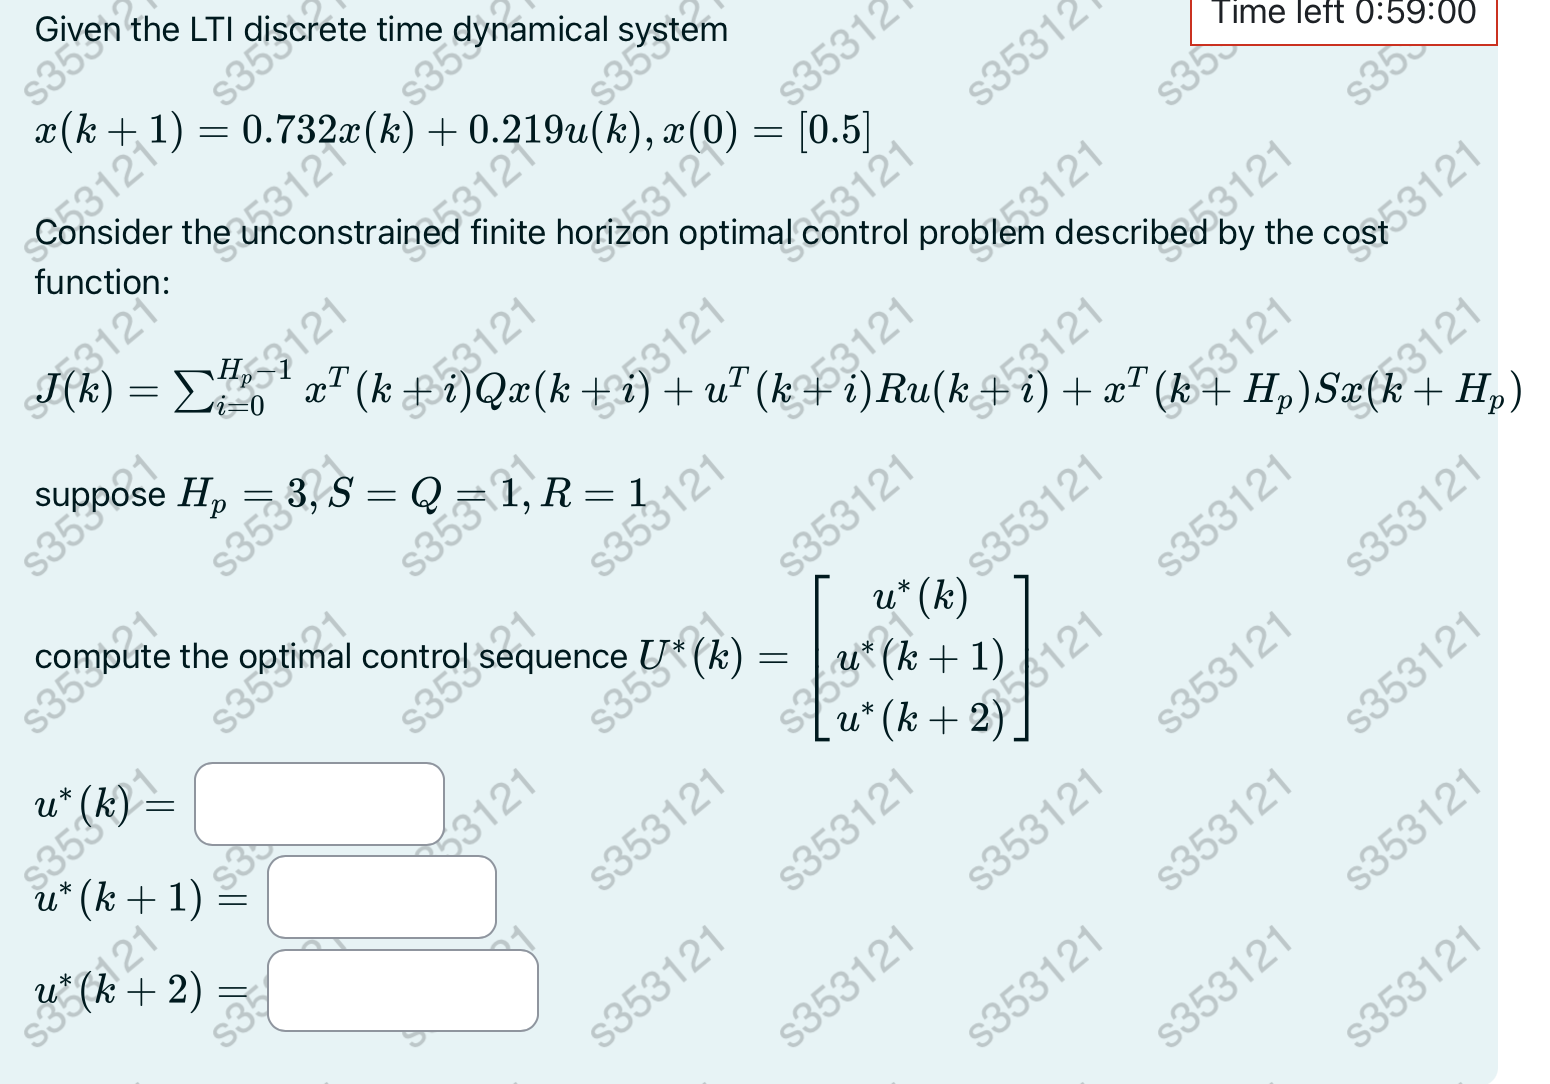

clear
A = 0.732;
B = 0.219;
x0 = 0.5;
Hp = 3;
Q = 1;
S = 1;
R = 1;
% note: try to be as parametric as possible since it could happen that
% we'll need again same code (with different values)
n = 1;
p = 1;
Acal = [A;A^2;A^3];
Bcal = [B zeros(n,1) zeros(n,1); A*B B zeros(n,1); A^2*B A*B B];
Qcal = blkdiag(Q,Q,Q);
Rcal = blkdiag(R,R,R);

H = 2*(Bcal'*Qcal*Bcal + Rcal);
F = 2*Acal'*Qcal*Bcal;

U = -H\F'*x0

U =    -0.1298
   -0.0763
   -0.0352


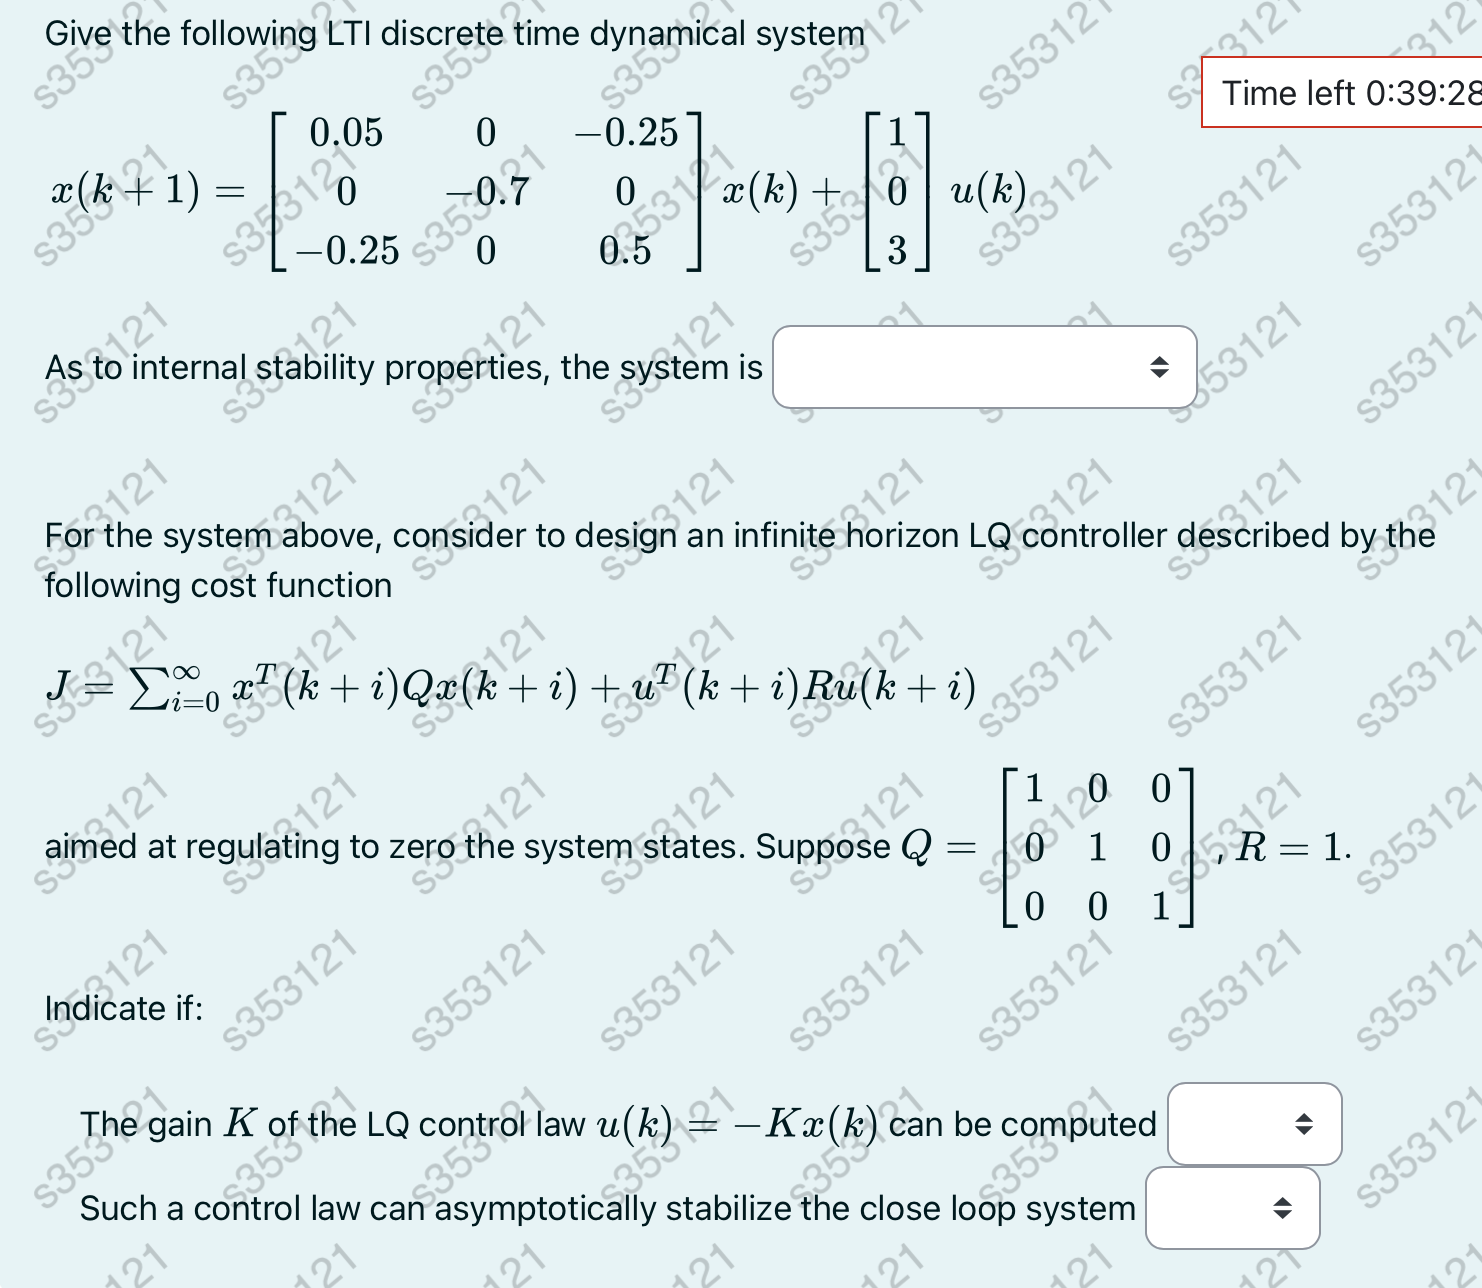

clear
A = [0.05 0 -0.25; 0 -0.7 0; -0.25 0 0.5];
B = [1; 0; 3];

% internal stability
eig(A) % -> asymp stable

ans =    -0.7000
   -0.0613
    0.6113



Mr = ctrb(A,B);
rank_Mr = rank(Mr) % -> is not full rank => we can't build K

rank_Mr = 2


% note: if rank was full but rank_Mo was not full => we could have built
% K but we weren't be able to asymptotically stabilize the close loop 
% system

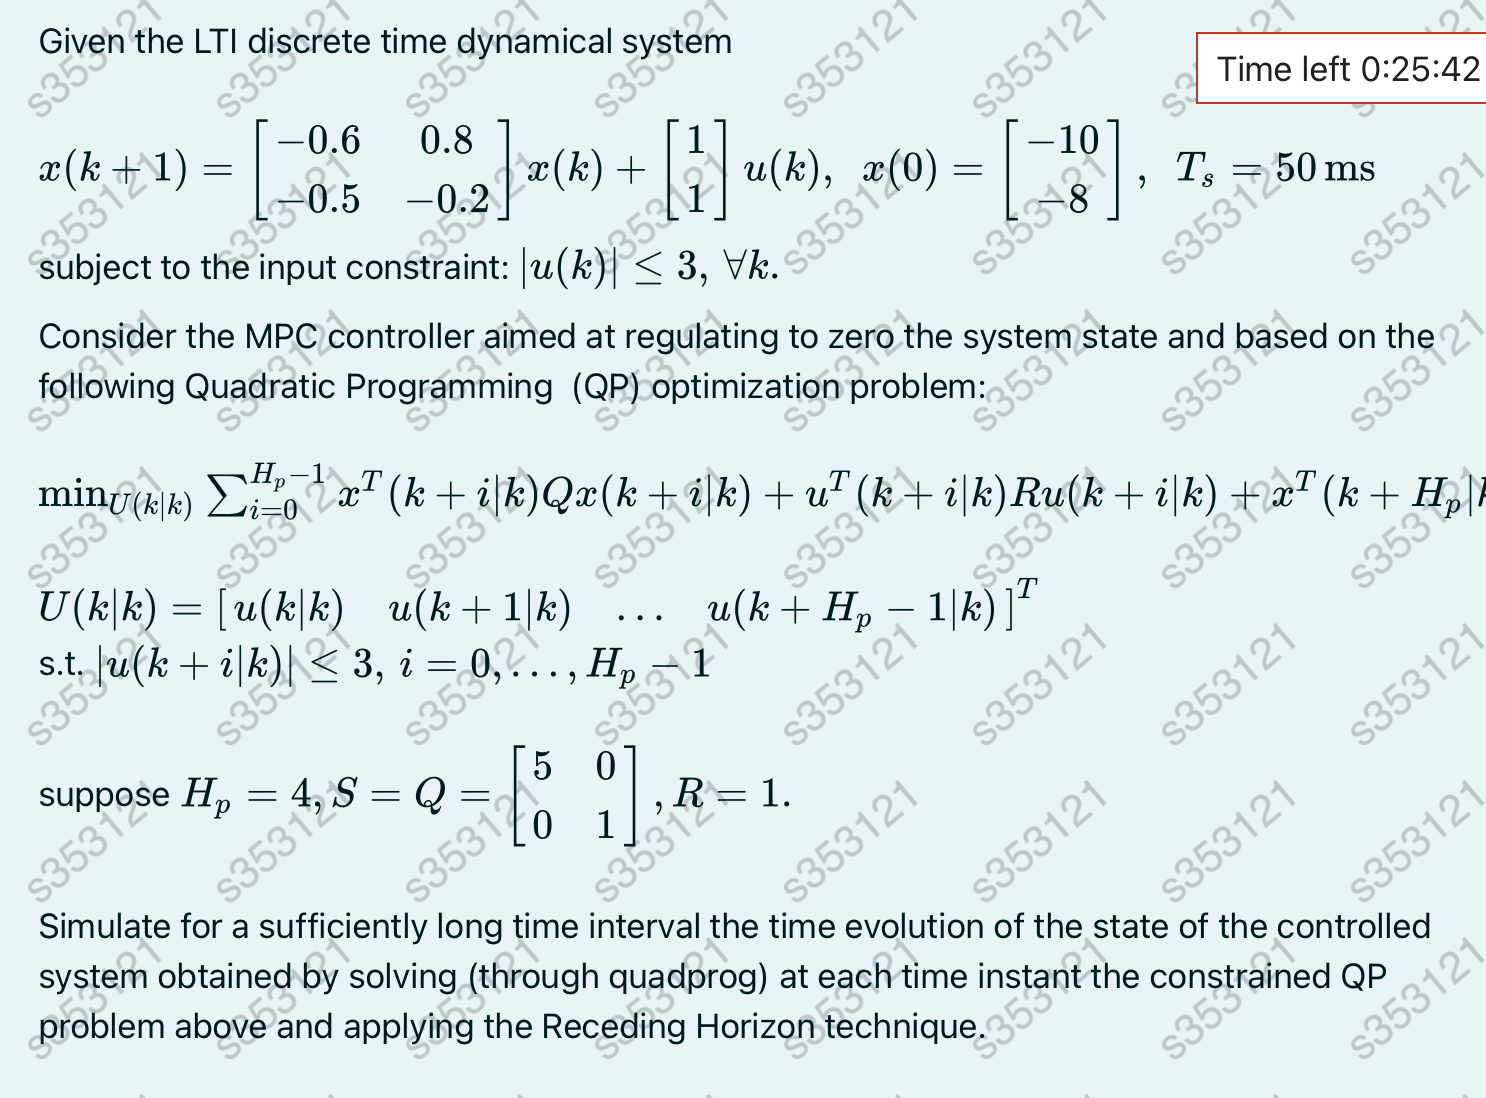

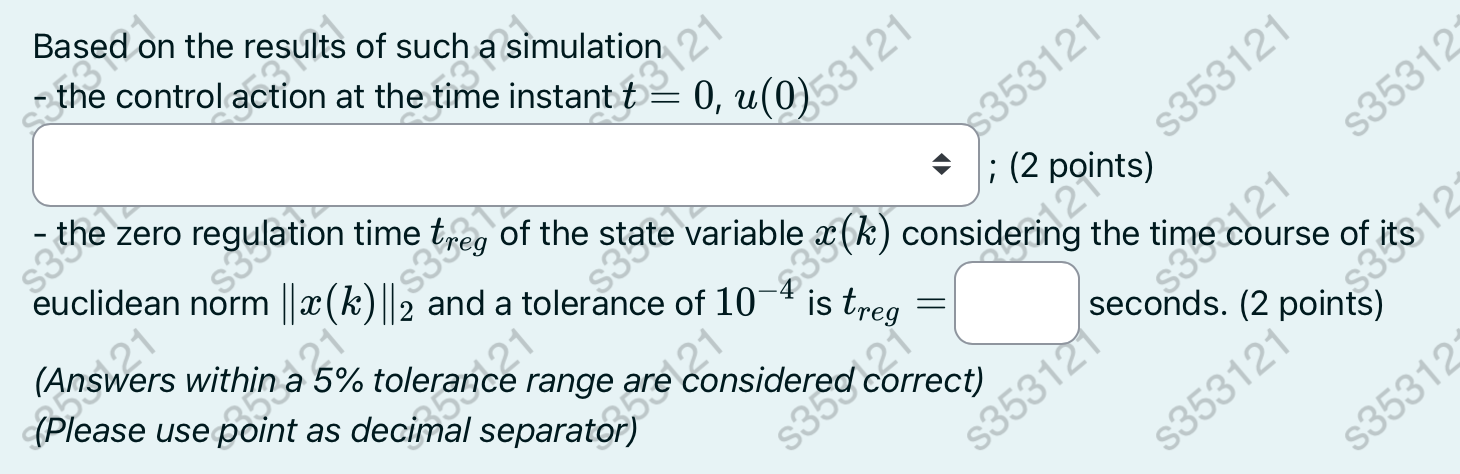

clear
A = [-0.6 0.8; -0.5 -0.2];
B = [1;1];
x0 = [-10;-8];
Ts = 50e-3;
Hp = 4;
Q = [5 0; 0 1];
S = Q;
R = 1;
n = 2;
p = 1;

Acal = [A;A^2;A^3; A^4];
Bcal = [B zeros(n,1) zeros(n,1) zeros(n,1); A*B B zeros(n,1) zeros(n,1); 
    A^2*B A*B B zeros(n,1); A^3*B A^2*B A*B B];
Qcal = blkdiag(Q,Q,Q,Q);
Rcal = blkdiag(R,R,R,R);

H = 2*(Bcal'*Qcal*Bcal + Rcal);
H = (H+H')/2;
F = 2*Acal'*Qcal*Bcal;

% input constraints
G = [eye(Hp); -eye(Hp)];
u_max = 3;
h = u_max*ones(2*Hp,1);

x_traj(:,1) = x0;
x_k = x0;
steps = 200;
for kk=1:steps
    U = quadprog(H,x_k'*F, G, h);
    x_traj(:, kk+1) = A*x_k + B*U(1);
    u_traj(kk) = U(1);
    x_k = x_traj(:, end);
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

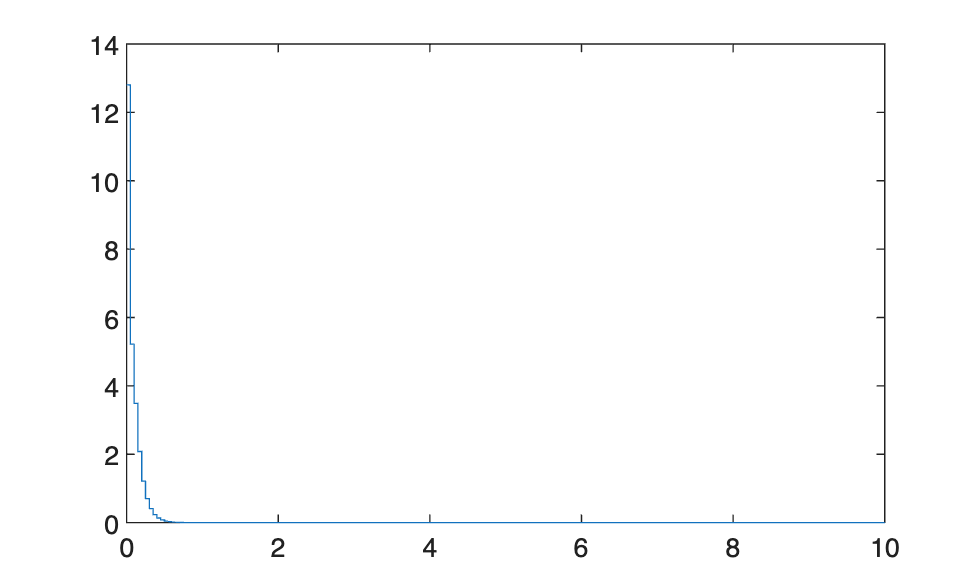


figure
stairs(0:Ts:Ts*steps, sqrt(x_traj(1,:).^2+x_traj(2,:).^2))

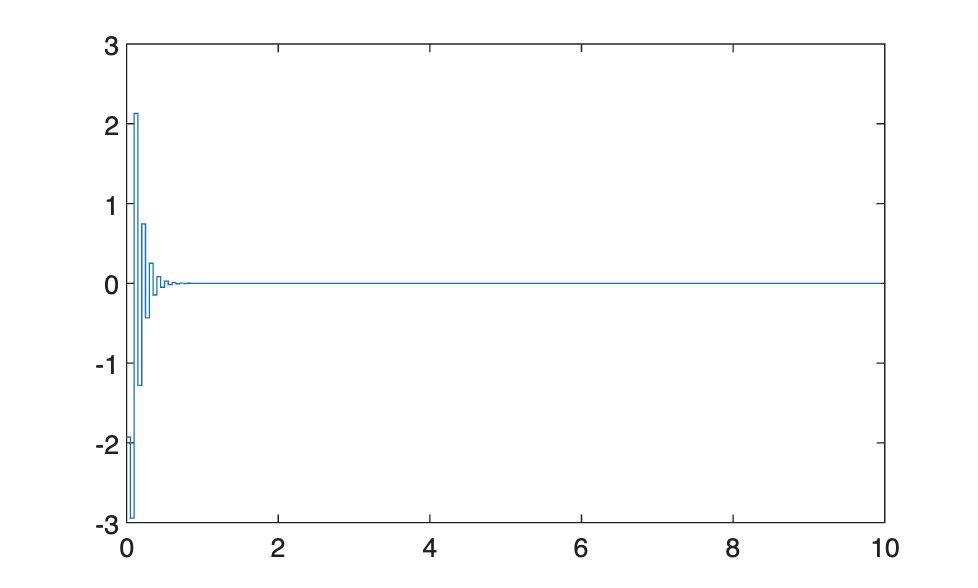


figure
stairs(0:Ts:Ts*(steps-1), u_traj)